# レギュラーシーズンの勝率からプレイオフを予測する

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

clear;clc;close all

データを読み込む(prog_NBADataConcatenation.mlxを実行しておく)

load('../data/NBAResults.mat');

2018-19シーズンのチームと試合を抽出する．

seasonStartYearVal=2018;
ind = tbl_teams.SeasonStartYear==seasonStartYearVal;
tbl_teams_tmp=tbl_teams(ind,:);
numTeams=size(unique(tbl_teams_tmp.TeamName),1);

試合は訓練用(train)とテスト用(test)に分ける

ind = tbl_results.SeasonStartYear==seasonStartYearVal ...
    & tbl_results.isRegular;
tbl_results_train=tbl_results(ind,:);

ind = tbl_results.SeasonStartYear==seasonStartYearVal ...
    & tbl_results.isPlayoff;
tbl_results_test=tbl_results(ind,:);

勝，負試合数，および得失点を集計する

集計用の変数を準備する

Wins=zeros(size(tbl_teams_tmp,1),1);
Loses=zeros(size(tbl_teams_tmp,1),1);
ScoresFor=zeros(size(tbl_teams_tmp,1),1);
ScoresAgainst=zeros(size(tbl_teams_tmp,1),1);

for n1=1:size(tbl_results_train,1)

それぞれの試合で両チームが何番に対応するかを見つける

    TeamANum=find(tbl_teams_tmp.TeamName==tbl_results_train.Home(n1));
    TeamBNum=find(tbl_teams_tmp.TeamName==tbl_results_train.Away(n1));

各チームの得失点を加える

    ScoresFor(TeamANum)=ScoresFor(TeamANum)+tbl_results_train.HomeScore(n1);
    ScoresFor(TeamBNum)=ScoresFor(TeamBNum)+tbl_results_train.AwayScore(n1);
    ScoresAgainst(TeamANum)=ScoresAgainst(TeamANum)+tbl_results_train.AwayScore(n1);
    ScoresAgainst(TeamBNum)=ScoresAgainst(TeamBNum)+tbl_results_train.HomeScore(n1);

得点の大小で場合分けし，勝・引分・負それぞれに加える

    if tbl_results_train.HomeScore(n1)>tbl_results_train.AwayScore(n1)
        Wins(TeamANum)=Wins(TeamANum)+1;
        Loses(TeamBNum)=Loses(TeamBNum)+1;
    elseif tbl_results_train.HomeScore(n1)<tbl_results_train.AwayScore(n1)
        Loses(TeamANum)=Loses(TeamANum)+1;
        Wins(TeamBNum)=Wins(TeamBNum)+1;
    end
end

勝率，得点割合の列を追加する

WinRatio=Wins./(Wins+Loses);
ScoreRatio=ScoresFor./(ScoresFor+ScoresAgainst);
tbl_teams_tmp=addvars(tbl_teams_tmp, WinRatio, ScoreRatio);

勝率→得失点割合の優先順でソートし，その順位を追加する

tbl_teams_tmp=sortrows(tbl_teams_tmp,{'WinRatio','ScoreRatio'},'descend')

tbl_teams_tmp = 30×8 table
    SeasonStr    SeasonStartYear           TeamName           Conference    Division     Abb    WinRatio    ScoreRatio
    _________    _______________    ______________________    __________    _________    ___    ________    __________

    2018-2019         2018          Milwaukee Bucks            Eastern      Central      MIL    0.73171       0.5195  
    2018-2019         2018          Toronto Raptors            Eastern      Atlantic     TOR    0.70732      0.51366  
    2018-2019         2018          Golden State Warriors      Western      Pacific      GSW    0.69512      0.51412  
    2018-2019         2018          Denver Nuggets             Western      Northwest    DEN    0.65854      0.50909  
    2018-2019         2018          Houston Rockets            Western      Southwest    HOU    0.64634      0.51069  
    2018-2019         2018          Portland Trail Blazers     Western      Northwest    POR    0.64634      0.50932  
    2018-2019       

RankByWins=(1:size(tbl_teams_tmp,1))';
tbl_teams_tmp=addvars(tbl_teams_tmp,RankByWins);

プレイオフの結果を予測する

予測と実際の結果を格納する変数を定義する

PredictionByWin=zeros(size(tbl_results_test,1),1);
ActualWin=zeros(size(tbl_results_test,1),1);
for n1=1:size(tbl_results_test,1)
   if tbl_results_test.HomeScore(n1)>tbl_results_test.AwayScore(n1)
        ActualWin(n1)=1;    %ホーム勝利を1と定義する
   else
        ActualWin(n1)=0;
   end

   TeamANum=find(tbl_teams_tmp.TeamName== tbl_results_test.Home(n1));
   TeamBNum=find(tbl_teams_tmp.TeamName== tbl_results_test.Away(n1));
   TeamARank=tbl_teams_tmp.RankByWins(TeamANum);
   TeamBRank=tbl_teams_tmp.RankByWins(TeamBNum);
   if TeamARank<TeamBRank
       PredictionByWin(n1)=1;
   else
       PredictionByWin(n1)=0;
   end
end

予測正解を判定する．

isPredictionCorrect= ActualWin==PredictionByWin;

予測正解率を算出する

predictionAccuracy=mean(isPredictionCorrect)

predictionAccuracy = 0.6951

結果と予測，予測正解かどうかを図示する

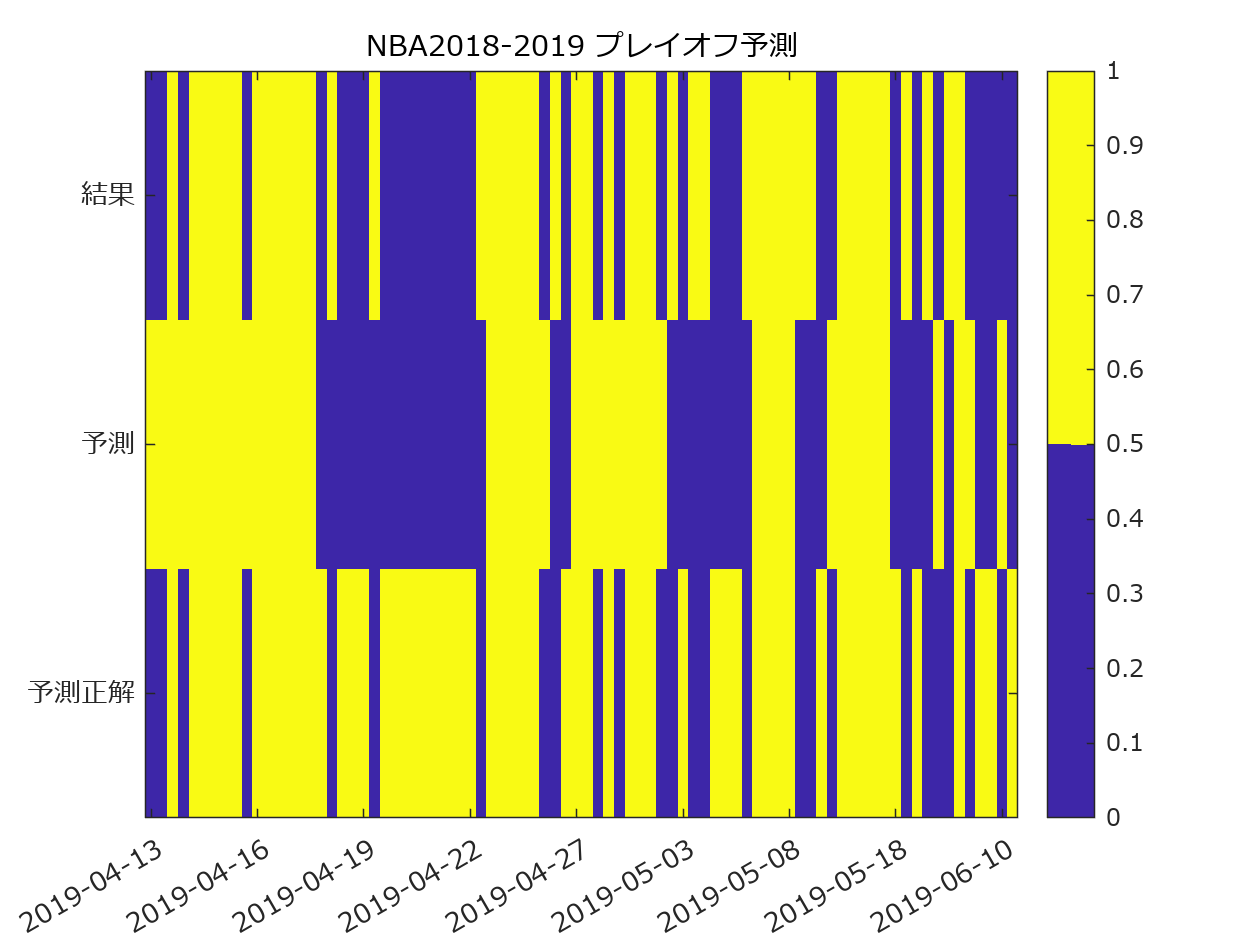

figure
imagesc([ActualWin PredictionByWin isPredictionCorrect]');
cmap=colormap(gca);
colormap(cmap([1,end],:));
colorbar;
set(gca,'fontname','メイリオ');
xticks(1:10:size(tbl_results_test,1));
xticklabels(string(tbl_results_test.Date(1:10:end)));
yticks(1:3);
yticklabels({'結果','予測','予測正解'});
title('NBA2018-2019 プレイオフ予測');
exportgraphics(gcf,'fig_NBA20182019PredictionByWins.pdf');

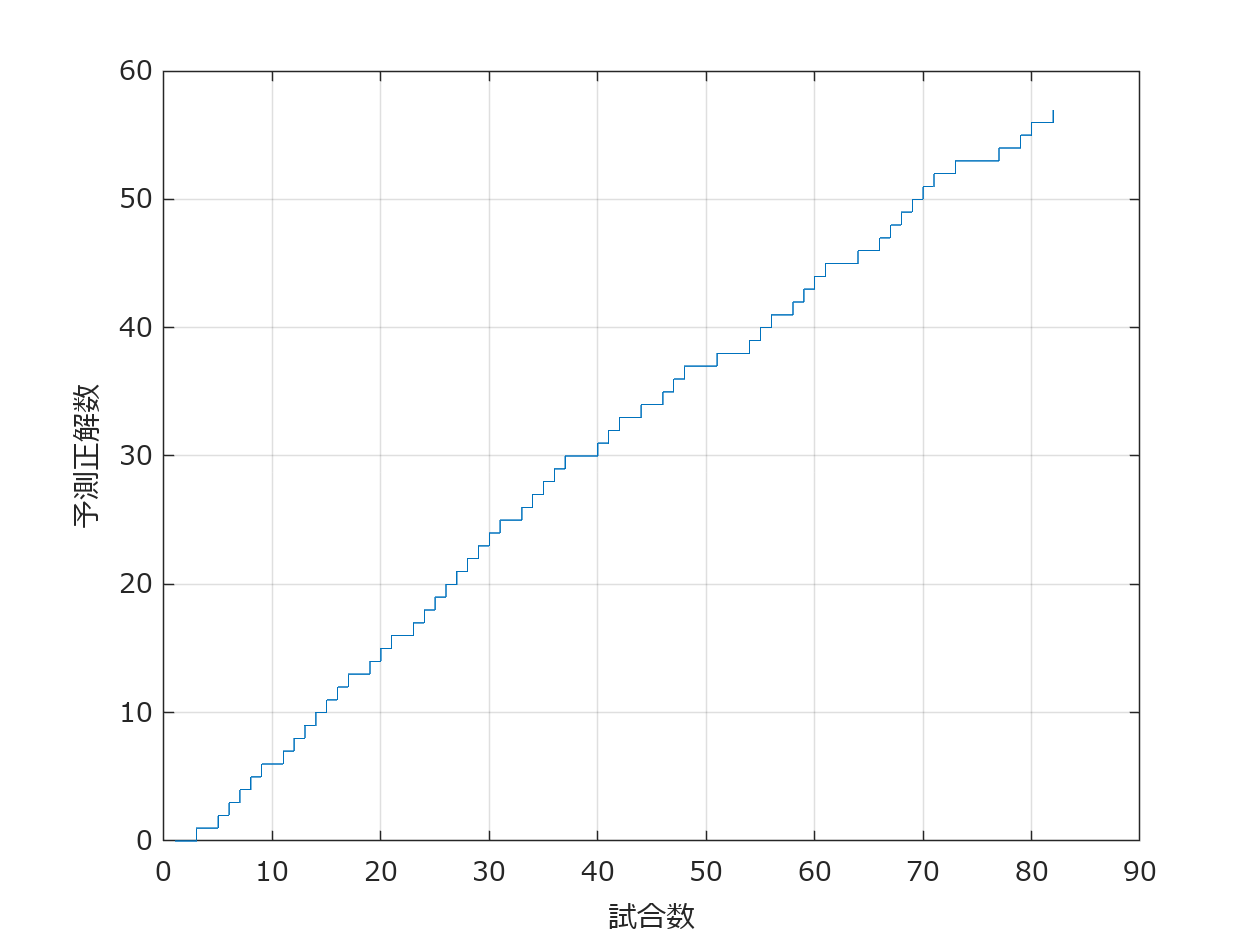

figure
stairs(cumsum(isPredictionCorrect));
grid on;
set(gca,'fontname','メイリオ');
xlabel('試合数');ylabel('予測正解数');
exportgraphics(gcf,'fig_NBA20182019CorrectPredictionsByWins.pdf');